% Guidemarks
pi=3.1416;
gmx = [0,0,4,4,0,0,4,4,0,4,0.4,3.6,2,2]';
gmy = [1.5,1.5,1.5,1.5,3.5,3.5,3.5,3.5,4.7,4.7,5,5,4.0,4.0]';
gmth = [pi,0,pi,0,pi,0,pi,0,0,pi,-pi/2,-pi/2,pi,0]';
gms = [gmx gmy gmth];

% Wall map
% bottom left
x1 = [0 0];
y1 = [1.8 0];
% bottom right
x2 = [2.2 0];
y2 = [4.0 0.0];
% top left
x3 = [0.0 5.0];
y3 = [1.8 5.0];
% top right
x4 = [2.2 5.0];
y4 = [4.0 5.0];
% left down
x5 = [0.0 0.0];
y5 = [0.0 1.8];
% left up
x6 = [0.0 3.2];
y6 = [0.0 5.0];
% right down
x7 = [4.0 0.0];
y7 = [4.0 1.8];
% right up
x8 = [4.0 3.2];
y8 = [4.0 5.0];
% maze bottom left
x9 = [0.9 3.1];
y9 = [1.7 3.1];
% maze bottom right
x10 = [2.3 3.1];
y10 = [3.1 3.1];
% maze left down
x11 = [1.7 2.5];
y11 = [1.7 3.1];
% maze left up
x12 = [0.9 3.1];
y12 = [0.9 4.3];
% maze right down
x13 = [2.3 2.5];
y13 = [2.3 3.1];
% maze right up
x14 = [3.1 3.1];
y14 = [3.1 4.3];
% maze middle horizontal
x15 = [1.5 3.7];
y15 = [2.5 3.7];
% maze middle vertical
x16 = [2.0 3.7];
y16 = [2.0 4.3];
% maze top
x17 = [0.9 4.3];
y17 = [3.1 4.3];

line_xs = [x1;x2;x3;x4;x5;x6;x7;x8;x9;x10;x11;x12;x13;x14;x15;x16;x17];
line_ys = [y1;y2;y3;y4;y5;y6;y7;y8;y9;y10;y11;y12;y13;y14;y15;y16;y17];

% Get odometry data
odo = load("odoPose.log");
hist = odo(:,2:4);
hist(:,1) = hist(:,1) + 0.25;
hist(:,2) = hist(:,2) + 0.25;

% Define Area of mystery
area = [1,1;3,1;3,2;1,2;1,1];

% Define objects   (0.4,0.3) (-0.3,0.4) (-0.4,-0.3)
obj1 = [1.2, 1.2; 1.6, 1.5; 1.45, 1.7; 1.05,1.4; 1.2,1.2];
obj2 = [2.3,1.2; 2.6,1.5; 2.3, 1.9;2.3,1.2];

% Read data from text file, which is returned by plugin.
fileID = fopen('output.txt','r');
formatSpec = '%f';
data = fscanf(fileID,formatSpec);
n = length(data);
xs = [];
ys = [];
for i = 1:n/2
    xs(i) = data(2*i-1);
    ys(i) = data(2*i);
end
xs

xs =     2.3024    2.3023    2.3022    2.3020    2.3025    2.3022    2.3026    2.3021    2.3024    2.3025    2.3026    2.3026    2.3025    2.3024    2.3021    2.3025    2.3021    2.3023    2.3024    2.3025    2.3024    2.3028    2.3026    2.3028    2.3024    2.3025    2.3024    2.3028    2.3026    2.3027    2.3028    2.3028    2.3031    2.3028    2.3029    2.3028    2.3032    2.3028    2.3028    2.3032    2.3029    2.3029    2.3032    2.3034    2.3033    2.3035    2.3035    2.3032    2.3032    2.3034


ys

ys =     1.9182    1.9135    1.9088    1.9041    1.8987    1.8940    1.8885    1.8837    1.8782    1.8727    1.8672    1.8616    1.8560    1.8504    1.8447    1.8383    1.8326    1.8262    1.8197    1.8131    1.8066    1.7992    1.7926    1.7852    1.7785    1.7710    1.7635    1.7552    1.7476    1.7391    1.7307    1.7222    1.7128    1.7043    1.6948    1.6853    1.6750    1.6654    1.6549    1.6436    1.6331    1.6216    1.6093    1.5969    1.5844    1.5710    1.5576    1.5441    1.5297    1.5143


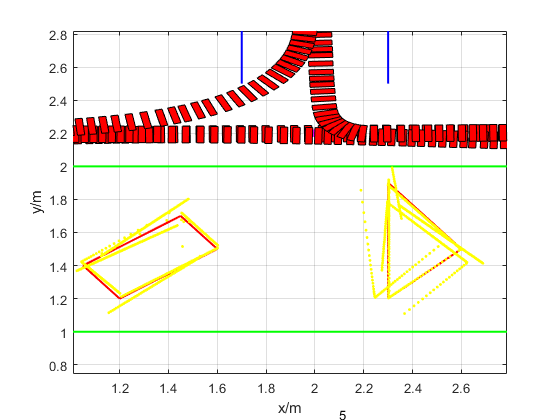

nodes = [-0.5,-0.5; 2,-0.5; 4.5,-0.5; % Nodes in the level of y = -0.5
            0.5,0.5; 2,0.5; 3.5,0.5; % y = 0.5
            -0.5,1.5; 0.5,1.5; 3.5,1.5; 4.5,1.5; % y = 1.5
            -0.5,2.2; 0.5,2.2; 2,2.2; 3.5,2.2; 4.5,2.2; % y=2.2
            -0.5,3.4; 0.5,3.4; 1.2,3.4; 2,3.4; 2.7,3.4; 3.5,3.4; 4.5,3.4;% y = 3.4
            1.2,4; 2.7,4; % y=4
             -0.5,4.6; 0.5,4.6; 2,4.6; 3.5,4.6; 4.5,4.6; % y= 4.6
             -0.5,5.5; 0.3,5.5; 2,5.5; 3.7,5.5; 4.5,5.5; % y = 5.5
             1.7, 4; 2.2, 4; % y=4
             ];
num = size(nodes);
num = num(1);
figure
% Draw walls
for i = 1:17
    pt1 = line_xs(i,:);
    pt2 = line_ys(i,:);
    grid on
    plot([pt1(1) pt2(1)], [pt1(2) pt2(2)],"LineWidth",1.5,"Color",'b')
    hold on
end
% Draw area where the obejct is
for i = 1:4
    pt1 = area(i,:);
    pt2 = area(i+1,:);
    grid on
    plot([pt1(1) pt2(1)], [pt1(2) pt2(2)],"LineWidth",1.5,"Color",'g')
    hold on
end
% Draw object 1
for i = 1:4
    pt1 = obj1(i,:);
    pt2 = obj1(i+1,:);
    grid on
    plot([pt1(1) pt2(1)], [pt1(2) pt2(2)],"LineWidth",1.5,"Color",'r')
    hold on
end
% Draw object 2
for i = 1:3
    pt1 = obj2(i,:);
    pt2 = obj2(i+1,:);
    grid on
    plot([pt1(1) pt2(1)], [pt1(2) pt2(2)],"LineWidth",1.5,"Color",'r')
    hold on
end
% Draw guidemarks
scatter(gms(:,1),gms(:,2),72,'red',"filled")
hold on

% Draw nodes
scatter(nodes(:,1),nodes(:,2),36,'magenta','filled')
hold on

% Add labels
labels = string(1:num);
text(nodes(:,1)+0.1,nodes(:,2),labels);
% Draw scanned data
scatter(xs,ys,5,'yellow','filled')
hold on

% Set axis ranges
axis([-1 5 -1 6])
plot_hist(hist, 700)
xlabel('x/m')
ylabel('y/m')
hold off

function plot_rectangle(x_coor, y_coor, angle, w, h)
    pos = [x_coor; y_coor];
    pos_1 = [-w/2;- h/2];
    pos_2 = [w/2;-h/2];
    pos_3 = [-w/2;h/2];
    pos_4 = [w/2;h/2];
    pose_1r = rot2(angle)*pos_1 + pos;
    pose_2r = rot2(angle)*pos_2 + pos;
    pose_3r = rot2(angle)*pos_3 + pos;
    pose_4r = rot2(angle)*pos_4 + pos;
    x = [pose_1r(1) pose_2r(1) pose_4r(1) pose_3r(1)];
    y = [pose_1r(2) pose_2r(2) pose_4r(2) pose_3r(2)];
    patch(x, y, 'red')
end

function plot_hist(hist, num)
    shape = size(hist);
    len = shape(1);
    step = max(5,round(len/num,0));
    if len >= 5
        for i = 1:step:len
        plot_rectangle(hist(i,1),hist(i,2),hist(i,3), 0.03,0.1)
        end
    end
end